# Sizing Battery for Electric Vehicle

Copyright 2022 - 2023 The MathWorks, Inc.

To return to the main page within this repository, [click here](matlab:open('ElectricVehicleDesignOverview.mlx')).

## Overview

Batteries are one of the most critical components on a battery electric vehicle (BEV) platform. Batteries provide energy for propulsion, heating, ventilation, and air conditioning (HVAC), coolant pumps and heaters, and in-vehicle lighting. You want a larger capacity battery pack from a range perspective, but larger batteries come at cost of increased weight of the vehicle. A larger capacity typically requires a larger volume, increasing the weight of the battery itself. The vehicle also needs more room to store the larger batteries, increasing the size and weight of the body of the vehicle. Larger capacity batteries also introduce additional safety and packaging considerations. The cost of the battery is also an important factor as batteries tend to be one of the most expensive components on the BEV platform. 

You need to achieve a balance between the capacity and size of the battery. For example, a 40 kWh battery can be 450 liters in volume and 300 kg in Mass, Increase in capacity increase both the volume and mass of the battery which is significant for a large component like a battery. In this example, you simulate battery packs with different capacities and weights, and compare them based on how these factors affect the range of the vehicle.

Open the `BEVplantModel `model.

open_system("BEVplantModel")

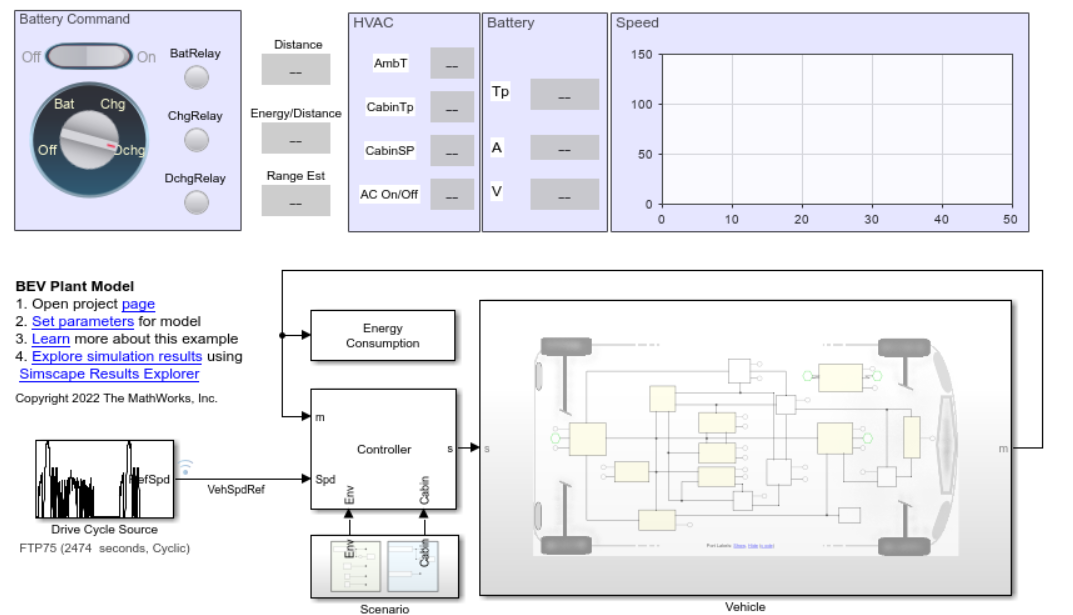

For more information on different BEV components, see [Battery Electric Vehicle Model](matlab:open('BEVModelMain.mlx')).

## Define Battery Pack Electrical Design

To open the battery model, double-click the Battery subsystem. The battery pack is modeled using Simscape Battery™ and the Pack subsystem is modeled using the Battery Pack Builder. The BMS subsystem defines the battery management system (controls).

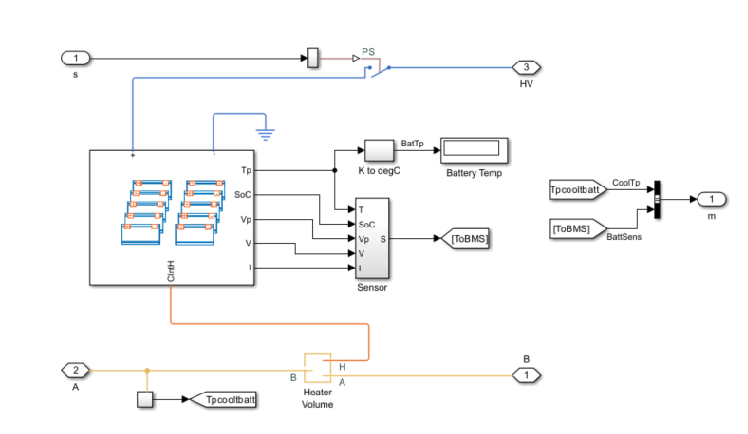

The battery comprises a battery pack of 400 V because 400 V is generally used in electric vehicles. Multiple cells are connected in series and parallel because a single cell cannot provide a voltage this high. The battery pack comprises 10 modules, each with 11 series-connected parallel sets (p-sets). Each p-set comprises three cells in series. All modules are connected in series to form a pack of 330 cells. The power of the battery pack is 40 kWh and the charge is 100 Ah.

## Define Battery Pack Options

In this example, you see how the increase in battery capacity affects the energy consumed per kilometer of the vehicle and the change in the overall range of the vehicle. For range calculations, you use the new european driving cycle (NEDC) cycle. You keep the number of series and parallel cells constant and change the battery cell capacity, which leads to changes in the battery pack size and weight.

The gravimetric energy density of a battery is the capacity to weight ratio and it is a key metric for battery design. The weight of the battery is the sum of the weight of all the battery cells, battery casing, connectors, and the auxiliaries attached to the battery pack. In this analysis, the gravimetric energy density of the pack is 80 Wh/kg; i.e. for every 80 Wh increase in battery pack capacity, 1 kg is added to the battery pack mass. The sizing is done for a 25 degC scenario, because the typical HVAC and auxiliary energy requirements are lower and a major portion of the energy the battery consumes is to satisfy the propulsion demand. 

You calculate the weight of the car as the sum of the body weight and the battery weight. For a 40 kWh battery with 80 Wh/kg gravimetric energy density, the mass is 500 kg. The vehicle body mass is taken as 1100 kg. The base length of the car is 3 m and mass per unit length of the vehicle is 367 kg/m. The volume of the battery increases by 90 Wh/l which roughly corresponds to 0.04 m length increase per kWh for a battery of a compact sedan. 

***Increase in battery mass = Increase in battery capacity(Wh) / (80 Wh/kg)***

***Increase in vehicle length = Extra battery capacity(kWh) * (0.04 m/kWh)***

***Increase in vehicle body mass = Increase in vehicle length(m) * (367 kg/m)***

***Increase in total Weight = Increase in vehicle body weight + Increase in battery weight***

Based on these values, for a 5 kWh increase in the capacity of the battery the mass increases by 135 kg.

## Run Simulations

For 40 kWh battery pack at 400 V, the vehicle mass is 1600 Kg including the battery pack. The battery pack mass is 500 kg. 

VehicleMass40KWh = 1600; % [kg] Mass of vehicle for 40 kWh battery
Ah40KWh = 34 ; % [Ah] Ampere hour for cell, 3 cell in series make 40 kWh battery capacity for 400V battery

For 45 kWh battery pack at 400 V. The vehicle mass is 1736 kg including the battery pack, battery pack mass is 562 kg.

gravBattWeight = 45*1000 / 80; % [kg] mass of battery pack
VehBodyWeight = 1100 + 367*5*0.04; % [kg] mass of vehicle body
VehicleMass45KWh = gravBattWeight + VehBodyWeight; % [kg] Total vehicle mass for 45 kWh battery pack
Ah45KWh = 37.5; % [Ah] Ampere hour for cell, 3 cell in series make 45 kWh battery capacity for 400V battery

To run the simulations for battery sizing, at the MATLAB command prompt, run the `BEVbatterySizing `script. To run the file using the toolbar or to edit options for the run, open [BEVbatterySizing](matlab:open('BEVbatterySizing.m')).

## Plot Estimated Range of BEV

Load the results computed upon executing `BEVbatterySizing`. Load the results for NEDC profile runs for the 40 kWh pack and 45 kWh pack.

% Load the simulation data
load('NEDCsizingData.mat')
%Tabulated comaprison of the run
DriveCycle = ["NEDC 40kWh";"NEDC 45kWh"];
Range = [NEDC40KWh.RangeRating;NEDC45KWh.RangeRating];
EM1Energy = [NEDC40KWh.EM1energy;NEDC45KWh.EM1energy];
EM2Energy = [NEDC40KWh.EM2energy;NEDC45KWh.EM2energy];
EnergyConsumed = [NEDC40KWh.Energy;NEDC45KWh.Energy];
HVACenergy = [NEDC40KWh.HVACenergy;NEDC45KWh.HVACenergy];
AuxEnergy = [NEDC40KWh.AuxEnergy; NEDC45KWh.AuxEnergy];

range_NEDC = table(DriveCycle,Range,EnergyConsumed,EM1Energy,EM2Energy,HVACenergy,AuxEnergy)

range_NEDC = 2×7 table
     DriveCycle     Range     EnergyConsumed    EM1Energy    EM2Energy    HVACenergy    AuxEnergy
    ____________    ______    ______________    _________    _________    __________    _________

    "NEDC 40kWh"    321.03        1388.8         1227.2       38.139        121.91       0.98269 
    "NEDC 45kWh"    343.73        1430.6           1269       38.134        121.91       0.98269 


For a 5 kWh increase in the capacity you get a 22 km increase in range. The energy consume increases from 124 Wh/km for the 40 kWh BEV to 131 Wh/km for the 45 kWh BEV. A 12.5% increase in battery capacity gives you a 7% increase in range but the energy consumption per km increases by 5.6%. The increase in size of the battery increases the range of the vehicle but it also increases the cost of the build and the cost of charging the battery as the energy consumed per km increases. You need to achieve an appropriate balance between these factors when sizing a battery pack for a BEV.

## Useful Links

[Electric Vehicle Design with Simscape](matlab:open('ElectricVehicleDesignOverview.mlx'))